lengthOfTime = 60*60*24; % [seconds]

%Define time range, initial conditions, and solve system
tRange = [0 lengthOfTime];
P0 = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

sol = ode45(@occupancyLevel, tRange, P0);

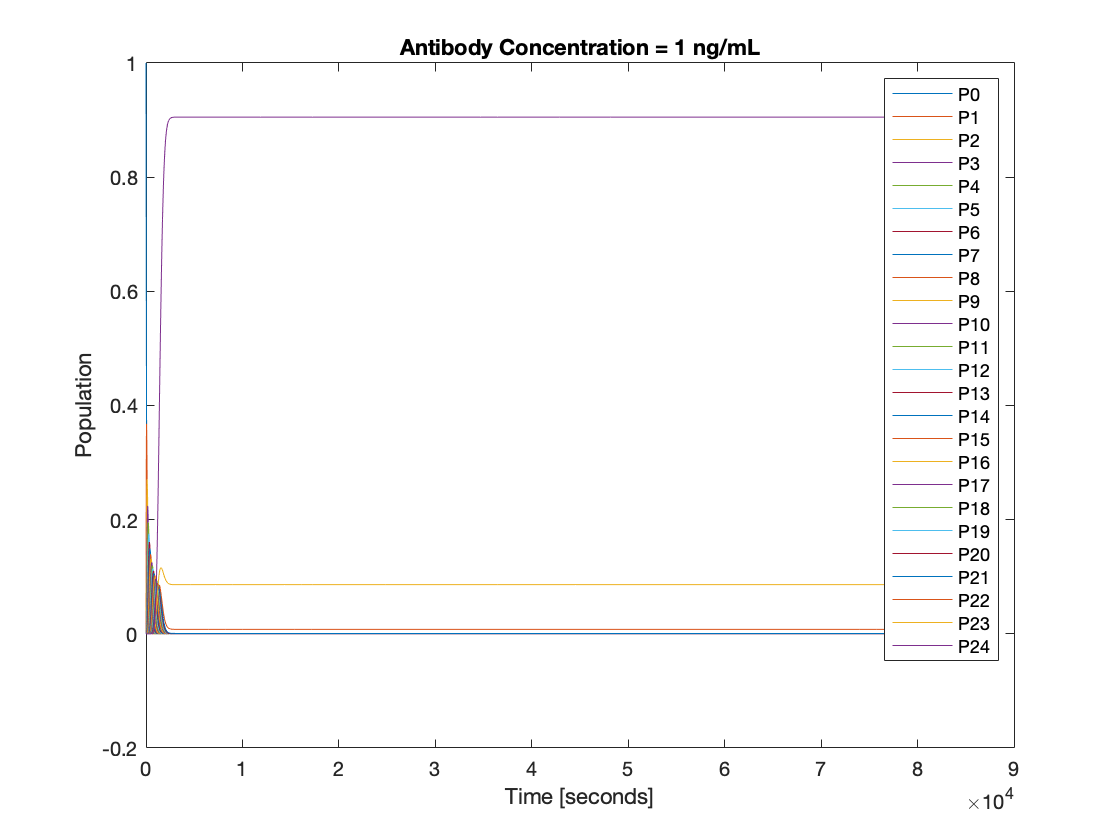

%Get t and P values
tSol = linspace(0, lengthOfTime, 10*lengthOfTime);
PSol = deval(sol,tSol);

%Isolate each occupancy level
P0 = PSol(1,:);
P1 = PSol(2,:);
P2 = PSol(3,:);
P3 = PSol(4,:);
P4 = PSol(5,:);
P5 = PSol(6,:);
P6 = PSol(7,:);
P7 = PSol(8,:);
P8 = PSol(9,:);
P9 = PSol(10,:);
P10 = PSol(11,:);
P11 = PSol(12,:);
P12 = PSol(13,:);
P13 = PSol(14,:);
P14 = PSol(15,:);
P15 = PSol(16,:);
P16 = PSol(17,:);
P17 = PSol(18,:);
P18 = PSol(19,:);
P19 = PSol(20,:);
P20 = PSol(21,:);
P21 = PSol(22,:);
P22 = PSol(23,:);
P23 = PSol(24,:);
P24 = PSol(25,:);

%Plot the Data
plot(tSol, P0)
hold on
plot(tSol, P1)
plot(tSol, P2)
plot(tSol, P3)
plot(tSol, P4)
plot(tSol, P5)
plot(tSol, P6)
plot(tSol, P7)
plot(tSol, P8)
plot(tSol, P9)
plot(tSol, P10)
plot(tSol, P11)
plot(tSol, P12)
plot(tSol, P13)
plot(tSol, P14)
plot(tSol, P15)
plot(tSol, P16)
plot(tSol, P17)
plot(tSol, P18)
plot(tSol, P19)
plot(tSol, P20)
plot(tSol, P21)
plot(tSol, P22)
plot(tSol, P23)
plot(tSol, P24)
hold off
legend("P0", "P1", "P2", "P3", "P4", "P5", "P6", "P7", "P8", "P9", "P10", "P11", "P12", "P13", "P14", "P15", "P16", "P17", "P18", "P19", "P20", "P21", "P22", "P23", "P24")
xlabel("Time [seconds]")
ylabel("Population")
title("Antibody Concentration = 1 ng/mL")

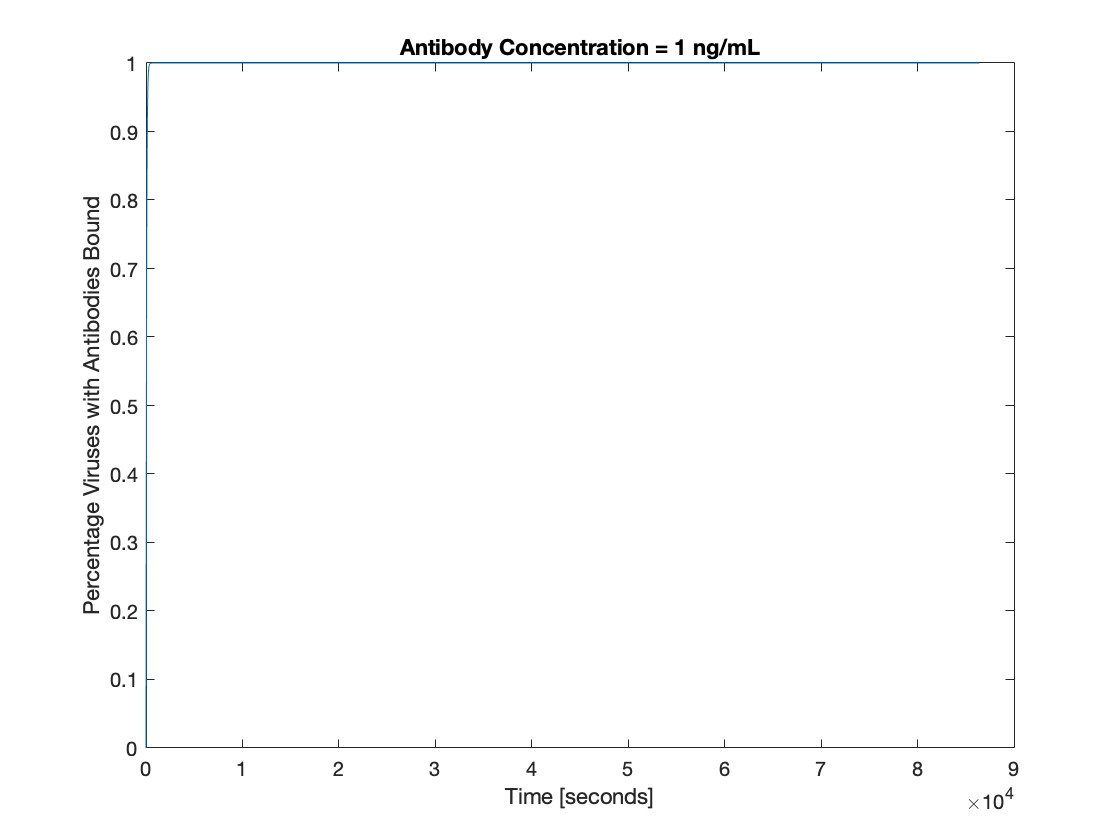

plot(tSol, 1-P0)
ylim([0 1]) 
xlabel("Time [seconds]")
ylabel("Percentage Viruses with Antibodies Bound")
title("Antibody Concentration = 1 ng/mL")

virusesWithBoundAntibodies = 1-P0(end);
maxVirusesWithBoundAntibodies = max(1-P0);

%Describe Infectivty 
I0 = 1; %inital infectivity
n = 24; %threshold of antibodies per virus

t = linspace(0, lengthOfTime, 10*lengthOfTime);
m = zeros(size(t)); %average number of antibodies per virus 
for pop = 0:24
    m = m + pop * PSol(pop+1,:);
end

I = zeros(1,length(tSol)); %infectivity 
for allTime = 1:length(tSol)
    for r = 0:(n-1)
        I(allTime) = I(allTime) + (m(allTime)^r) * exp(-m(allTime)) / factorial(r);
    end
end

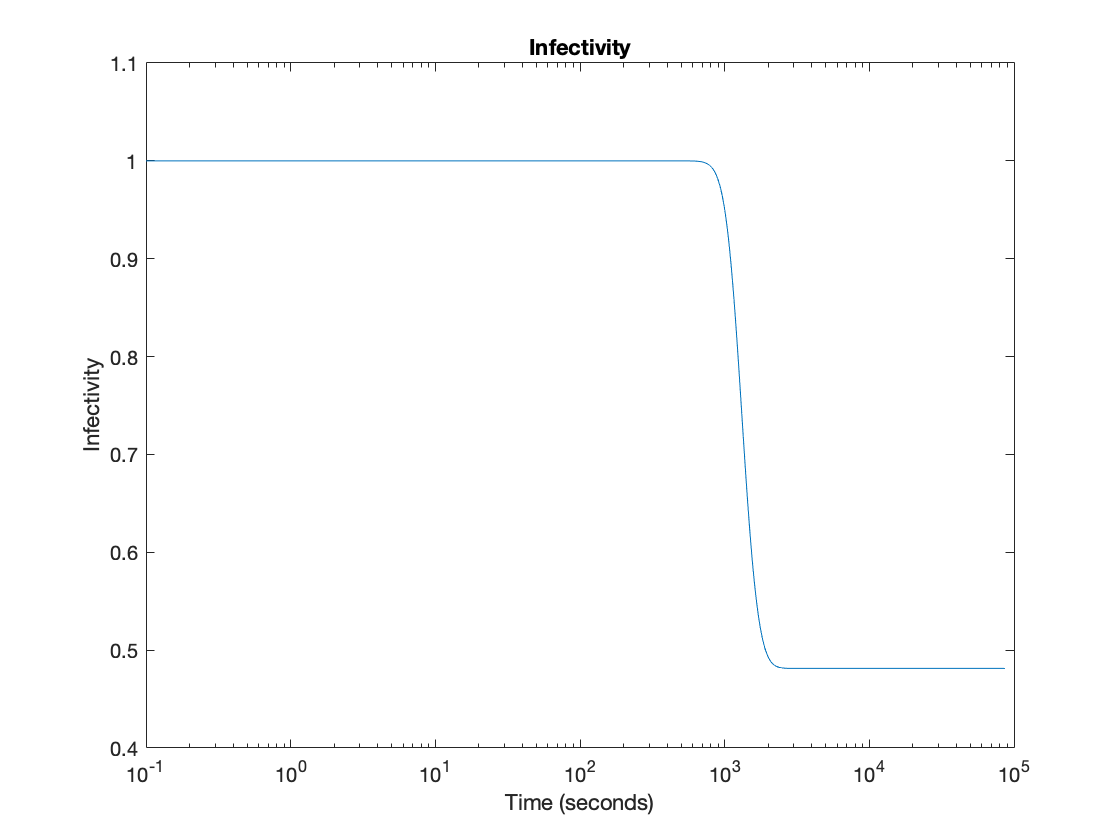

semilogx(tSol, I)
xlabel("Time (seconds)")
ylabel("Infectivity")
title("Infectivity")

%Linear Infectivity
antiinfectivity = 0;
for pop = 0:24
    antiinfectivity = antiinfectivity + (PSol(pop+1,end) * pop/24);
end
infectivity = 1 - antiinfectivity

infectivity = 0.0043

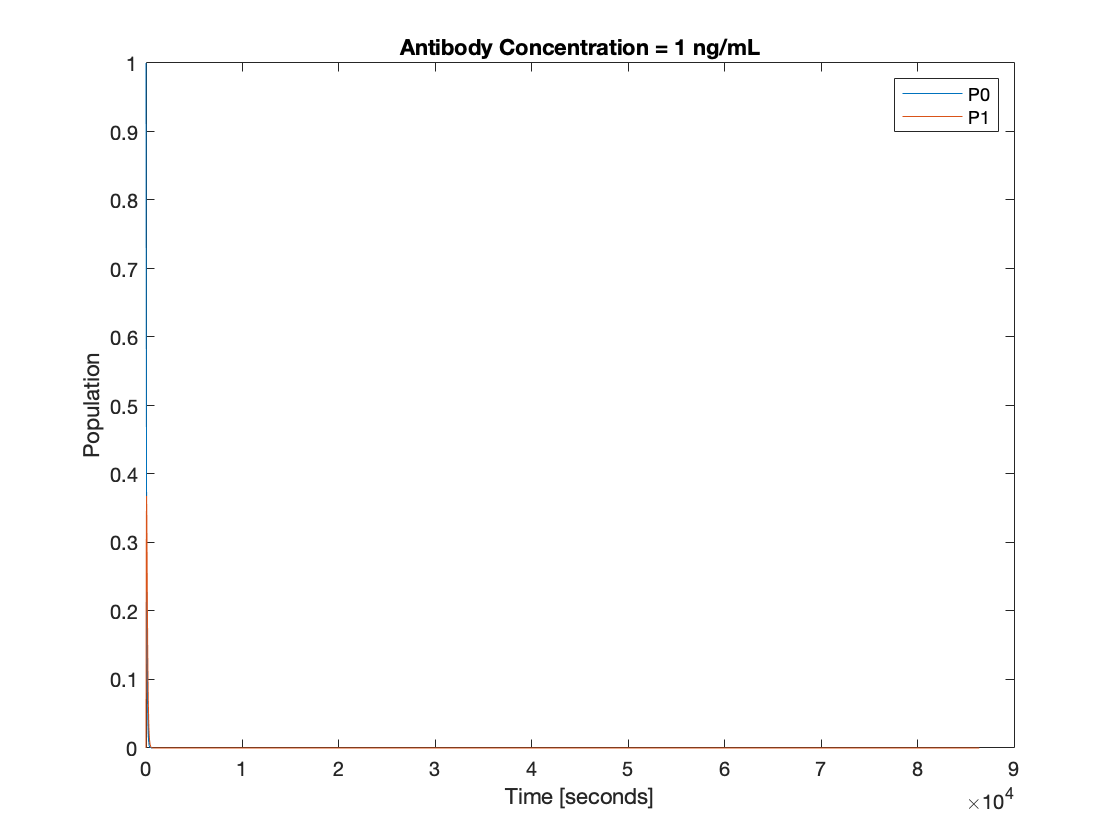

%Plot the Data
plot(tSol, P0)
hold on
plot(tSol, P1)
hold off
legend("P0", "P1")
xlabel("Time [seconds]")
ylabel("Population")
title("Antibody Concentration = 1 ng/mL")

diff = zeros(1, length(P0)-1);
for s = 1:(length(P0)-1)
    diff(s) = abs(P0(s+1) - P0(s));
end

count = 1;
threshold = 10^-8;

while diff(count) > threshold
    P0(count+1);
    count = count + 1;
end

steadyStateValue = 1 - P0(count+1)

steadyStateValue = 1.0000

steadyStateTime = tSol(count+1)

steadyStateTime = 715.9008

function dPdt = occupancyLevel (t, P)
    
    % Variables
    P0 = P(1);
    P1 = P(2);
    P2 = P(3);
    P3 = P(4);
    P4 = P(5);
    P5 = P(6);
    P6 = P(7);
    P7 = P(8);
    P8 = P(9);
    P9 = P(10);
    P10 = P(11);
    P11 = P(12);
    P12 = P(13);
    P13 = P(14);
    P14 = P(15);
    P15 = P(16);
    P16 = P(17);
    P17 = P(18);
    P18 = P(19);
    P19 = P(20);
    P20 = P(21);
    P21 = P(22);
    P22 = P(23);
    P23 = P(24);
    P24 = P(25);

    %Constants
    kon = 1.62 * 10^6; % M^-1 s^-1 
    koff = 6.82 * 10^(-5); % s^-1
    
    avogadrosNumber = 6.0221409 * 10^23; % mol^-1 
    
    %Conversions
    kDaPerGram = 6.022 * 10^20; % kDa/g
    ngPerGram = 10^9; %ng/g 
    mlPerLiter = 1000; %mL/L 
    
    %Concentration of Antibodies
    mAb = 10^3; %ng/mL 
    %%%% CONFIRM
    
    antibody10933Mass = 47.44; % kDa/molecule
    antibody10987Mass = 46.79; % kDa/molecule
    
    averageAntibodyMass = (antibody10933Mass + antibody10987Mass) / kDaPerGram * avogadrosNumber; % g/mol
    
    mAbConc = mAb / ngPerGram * mlPerLiter / averageAntibodyMass; 
  
    %Differential Equations
    dP0dt =                                              (1  * koff * P1)  - (kon * mAbConc * P0); 
    dP1dt =  (kon * mAbConc * P0)  - (1  * koff * P1)  + (2  * koff * P2)  - (kon * mAbConc * P1);
    dP2dt =  (kon * mAbConc * P1)  - (2  * koff * P2)  + (3  * koff * P3)  - (kon * mAbConc * P2);
    dP3dt =  (kon * mAbConc * P2)  - (3  * koff * P3)  + (4  * koff * P4)  - (kon * mAbConc * P3);
    dP4dt =  (kon * mAbConc * P3)  - (4  * koff * P4)  + (5  * koff * P5)  - (kon * mAbConc * P4);
    dP5dt =  (kon * mAbConc * P4)  - (5  * koff * P5)  + (6  * koff * P6)  - (kon * mAbConc * P5); 
    dP6dt =  (kon * mAbConc * P5)  - (6  * koff * P6)  + (7  * koff * P7)  - (kon * mAbConc * P6);
    dP7dt =  (kon * mAbConc * P6)  - (7  * koff * P7)  + (8  * koff * P8)  - (kon * mAbConc * P7);
    dP8dt =  (kon * mAbConc * P7)  - (8  * koff * P8)  + (9  * koff * P9)  - (kon * mAbConc * P8);
    dP9dt =  (kon * mAbConc * P8)  - (9  * koff * P9)  + (10 * koff * P10) - (kon * mAbConc * P9);
    dP10dt = (kon * mAbConc * P9)  - (10 * koff * P10) + (11 * koff * P11) - (kon * mAbConc * P10);
    dP11dt = (kon * mAbConc * P10) - (11 * koff * P11) + (12 * koff * P12) - (kon * mAbConc * P11);
    dP12dt = (kon * mAbConc * P11) - (12 * koff * P12) + (13 * koff * P13) - (kon * mAbConc * P12);
    dP13dt = (kon * mAbConc * P12) - (13 * koff * P13) + (14 * koff * P14) - (kon * mAbConc * P13);
    dP14dt = (kon * mAbConc * P13) - (14 * koff * P14) + (15 * koff * P15) - (kon * mAbConc * P14);
    dP15dt = (kon * mAbConc * P14) - (15 * koff * P15) + (16 * koff * P16) - (kon * mAbConc * P15);
    dP16dt = (kon * mAbConc * P15) - (16 * koff * P16) + (17 * koff * P17) - (kon * mAbConc * P16);
    dP17dt = (kon * mAbConc * P16) - (17 * koff * P17) + (18 * koff * P18) - (kon * mAbConc * P17);
    dP18dt = (kon * mAbConc * P17) - (18 * koff * P18) + (19 * koff * P19) - (kon * mAbConc * P18);
    dP19dt = (kon * mAbConc * P18) - (19 * koff * P19) + (20 * koff * P20) - (kon * mAbConc * P19);
    dP20dt = (kon * mAbConc * P19) - (20 * koff * P20) + (21 * koff * P21) - (kon * mAbConc * P20);
    dP21dt = (kon * mAbConc * P20) - (21 * koff * P21) + (22 * koff * P22) - (kon * mAbConc * P21);
    dP22dt = (kon * mAbConc * P21) - (22 * koff * P22) + (23 * koff * P23) - (kon * mAbConc * P22);
    dP23dt = (kon * mAbConc * P22) - (23 * koff * P23) + (24 * koff * P24) - (kon * mAbConc * P23);
    dP24dt = (kon * mAbConc * P23) - (24 * koff * P24);
 
    dPdt = [dP0dt; dP1dt; dP2dt; dP3dt; dP4dt; dP5dt; dP6dt; dP7dt; dP8dt; dP9dt; dP10dt; dP11dt; dP12dt; dP13dt; dP14dt; dP15dt; dP16dt; dP17dt; dP18dt; dP19dt; dP20dt; dP21dt; dP22dt; dP23dt; dP24dt];
end








